# Simulazione Filtri

### creazione variabili

syms R1 R2 C1 C2 omega
assume(R1,{'positive','real'});
assume(R2,{'positive','real'});
assume(C1,{'positive','real'});
assume(C2,{'positive','real'});
assume(omega,{'positive','real'});
R1_val = 100E+3;   % 100 kOhm
R2_val = 1E+3;     % 1kOhm
C1_val = 47E-9;    % 47nF
C2_val = 100E-9;   % 100nF

## CRRC

Metto che inizialmente il segnale ha valore unitario

Dopo il primo attenuatore, il segnale ha una tensione Vth con un impedenza di uscita Rth:

[Vth, Rth] = calcola_thevenen(impedenza_condensatore(C1, omega), R1)

$$Vth = -\frac{1}{-1+\frac{\mathrm{i}}{C_{1}\,R_{1}\,\omega }}$$

$$Rth = \frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}$$

syms omega_1 omega_2
assume(omega_1,{'positive','real'});
assume(omega_2,{'positive','real'});

il ramo a destra ha un'impedenza z2:

Z2 = impedenza_condensatore(C2, omega) + R2

$$Z2 = R_{2}-\frac{\mathrm{i}}{C_{2}\,\omega }$$

Allora su questo ramo ci scorre una corrente I2

I2 = Vth / (Rth + Z2)

$$I2 = -\frac{1}{\left(-1+\frac{\mathrm{i}}{C_{1}\,R_{1}\,\omega }\right)\,\left(R_{2}+\frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}-\frac{\mathrm{i}}{C_{2}\,\omega }\right)}$$

allora la tensione in uscita è:

Vout = I2 * impedenza_condensatore(C2, omega)

$$Vout = \frac{\mathrm{i}}{C_{2}\,\omega \,\left(-1+\frac{\mathrm{i}}{C_{1}\,R_{1}\,\omega }\right)\,\left(R_{2}+\frac{1}{\frac{1}{R_{1}}+C_{1}\,\omega \,\mathrm{i}}-\frac{\mathrm{i}}{C_{2}\,\omega }\right)}$$

Vout = simplify(subs(Vout, R2, 1 / (omega_2 * C2)));
Vout = simplify(subs(Vout, R1, 1 / (omega_1 * C1)))

$$Vout = -\frac{\mathrm{i}}{C_{2}\,\left(\omega -\omega_{1}\,\mathrm{i}\right)\,\left(\frac{1}{C_{2}\,\omega_{2}}-\frac{\mathrm{i}}{C_{2}\,\omega }+\frac{1}{C_{1}\,\left(\omega_{1}+\omega \,\mathrm{i}\right)}\right)}$$

A = sqrt((conj(Vout) * Vout))

$$A = \frac{\sqrt{\frac{1}{\left(\omega -\omega_{1}\,\mathrm{i}\right)\,\left(\omega +\omega_{1}\,\mathrm{i}\right)\,\left(\frac{1}{C_{2}\,\omega_{2}}-\frac{1}{C_{1}\,\left(-\omega_{1}+\omega \,\mathrm{i}\right)}+\frac{\mathrm{i}}{C_{2}\,\omega }\right)\,\left(\frac{1}{C_{2}\,\omega_{2}}-\frac{\mathrm{i}}{C_{2}\,\omega }+\frac{1}{C_{1}\,\left(\omega_{1}+\omega \,\mathrm{i}\right)}\right)}}}{C_{2}}$$

A = simplify(A)

$$A = \frac{C_{1}\,\omega \,\omega_{2}}{\sqrt{{C_{1}}^{2}\,\omega^{4}+{C_{1}}^{2}\,\omega^{2}\,{\omega_{1}}^{2}+{C_{1}}^{2}\,\omega^{2}\,{\omega_{2}}^{2}+{C_{1}}^{2}\,{\omega_{1}}^{2}\,{\omega_{2}}^{2}+2\,C_{1}\,C_{2}\,\omega^{2}\,\omega_{1}\,\omega_{2}+2\,C_{1}\,C_{2}\,\omega^{2}\,{\omega_{2}}^{2}+{C_{2}}^{2}\,\omega^{2}\,{\omega_{2}}^{2}}}$$

tanTheta = simplify(imag(Vout) / real(Vout))

$$tanTheta = \frac{C_{1}\,\left(\omega_{1}\,\omega_{2}-\omega^{2}\right)}{\omega \,\left(C_{1}\,\omega_{1}+C_{1}\,\omega_{2}+C_{2}\,\omega_{2}\right)}$$

Il guadagno quindi è:

tmp = Vout;
tmp = subs(tmp, C1, C1_val);
tmp = subs(tmp, C2, C2_val);
tmp = subs(tmp, R1, R1_val);
tmp = subs(tmp, R2, R2_val);
guadagno_val = abs(tmp)^2;
sfasamento_val = angle(tmp);

### Plot

Prima troviamo l'espressione con i nostri parametri:

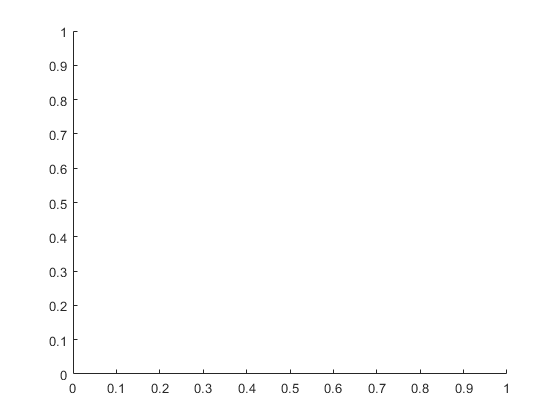

Error using fplot>singleFplot (line 240)
Input must be a function or functions of a single variable.

Error in fplot>@(f)singleFplot(cax,{f},limits,extraOpts,args) (line 200)
        hObj = cellfun(@(f) singleFplot(cax,{f},limits,extraOpts,args),fn{1},'UniformOutput',false);

Error in 


fplot(guadagno_val, [100 100000], "MeshDensity", 10)

set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
fplot(sfasamento_val, [100 100000], "MeshDensity", 10)
set(gca, 'XScale', 'log')

## RCCR

La prima parte è come prima, ma sono scambiati i componenti

[Vth, Rth] = calcola_thevenen(R2, impedenza_condensatore(C2, omega));
Z2 = impedenza_condensatore(C1, omega) + R1;
I2 = Vth / (Rth + Z2);
Vout = I2 * R1
tmp = Vout;
tmp = subs(tmp, C1, C1_val);
tmp = subs(tmp, C2, C2_val);
tmp = subs(tmp, R1, R1_val);
tmp = subs(tmp, R2, R2_val);
guadagno_val = abs(tmp)^2;
sfasamento_val = angle(tmp);

### Plot

fplot(guadagno_val, [10 100000], "MeshDensity", 10)
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
fplot(sfasamento_val, [10 100000], "MeshDensity", 10)
set(gca, 'XScale', 'log')

#### Funzioni thevenen

function [ratio_Vth_Vin, Rth] = calcola_thevenen(r1, r2)
    ratio_Vth_Vin = 1 / (r1/r2 + 1);
    Rth = 1 / (1/r1 + 1/r2);
end
function [Z] = impedenza_condensatore(c, omega)
    Z = 1 / (j  * omega * c);
end